%% Robotics System Assignment 3 Matlab Code

%   The University of Melbourne
%   MCEN90028 ROBOTICS SYSTEMS
%   GROUP 3
%   Written by: Hai Dang Nguyen

close all;
clear all;
clc;
time = 5;
t_i = 0;
t_f = time;

% Obtain Xi and Xf in frame 0 using ChessBoardLocation function
% Move 4 sqaure positive Y axis
% f4 -> b4
[XI,XF] = ChessBoardLocation('f4','b4');
% g1 -> f3
% [XI,XF] = ChessBoardLocation('g1','f3')


arrayOfcoeffa = zeros([3,4]);
size = 11;
xAndvWTime = zeros([3,size,3]); % x, v, time

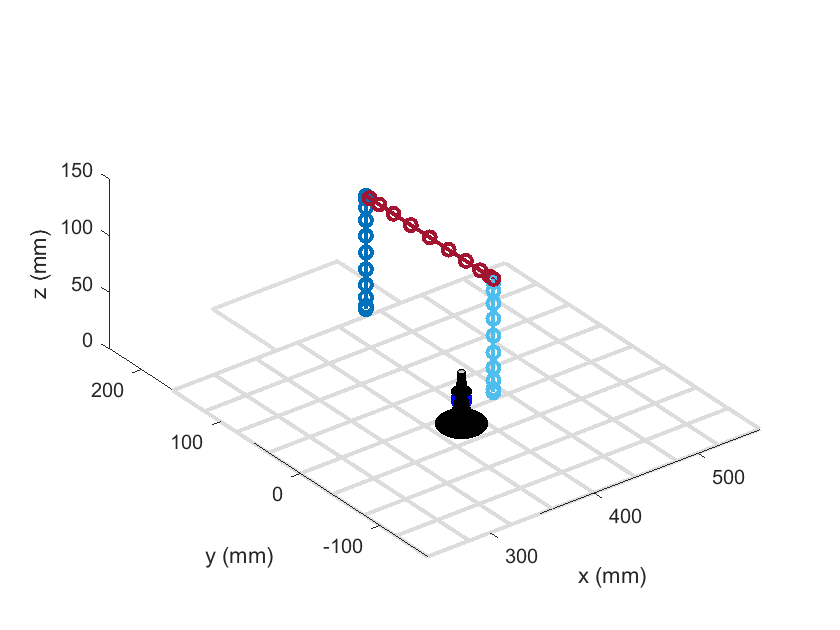

% With via points
figure(3);
title('Location of the end-effector');
plotChessBoard();hold on;
via_points = [[XI(1:2);XI(3)+100],[XF(1:2);XF(3)+100]];     % Each column is one via point
no_via_points = length(via_points(1,:));
no_segments = no_via_points +1;
v = 1;
points =[[XI]];
for v = 1:no_via_points
    points(:,length(points(1,:))+1) = via_points(:,v);
end
points(:,length(points(1,:))+1) = XF;
Arrays_coeff = [];
x_array = [];y_array = [];z_array = [];
t_array = [];R_t_array = [];

time = getTimeArray(points,t_i, t_f);

% Find segments for trajectories
for i = 1:no_segments
    for j = 1:3
%         [array_coeff(j,:),xAndvWTime(j,:,:)] = solveForSpline(points(j,i),points(j,i+1),0,0,t_i + (i-1)*t_f/no_segments,i*t_f/no_segments);
        [array_coeff(j,:),xAndvWTime(j,:,:)] = solveForSpline(points(j,i),points(j,i+1),0,0,time(i),time(i+1));

    end
    
    
    Arrays_coeff = [Arrays_coeff;array_coeff(:,:)];
    figure(3);
    plot3(xAndvWTime(1,:,1),xAndvWTime(2,:,1),xAndvWTime(3,:,1),'-o','LineWidth',2);hold on;
    x_array(:,i) = xAndvWTime(1,:,1);
    y_array(:,i) = xAndvWTime(2,:,1);
    z_array(:,i) = xAndvWTime(3,:,1);
    t_array(:,i) = xAndvWTime(1,:,3);
    % obtain the interpolating orientation
    [phi_coeff(i,:),phi_omega_time(i,:,:), k_hat(:,i), R_t_array(i,:,:,:)] = InterpolatingOrientation(points(:,i),points(:,i+1),time(i),time(i+1));


end
xlabel('x (mm)');
ylabel('y (mm)');
zlabel('z (mm)');
title('')
plotChessPiece(380,-20,0,50,20);axis equal

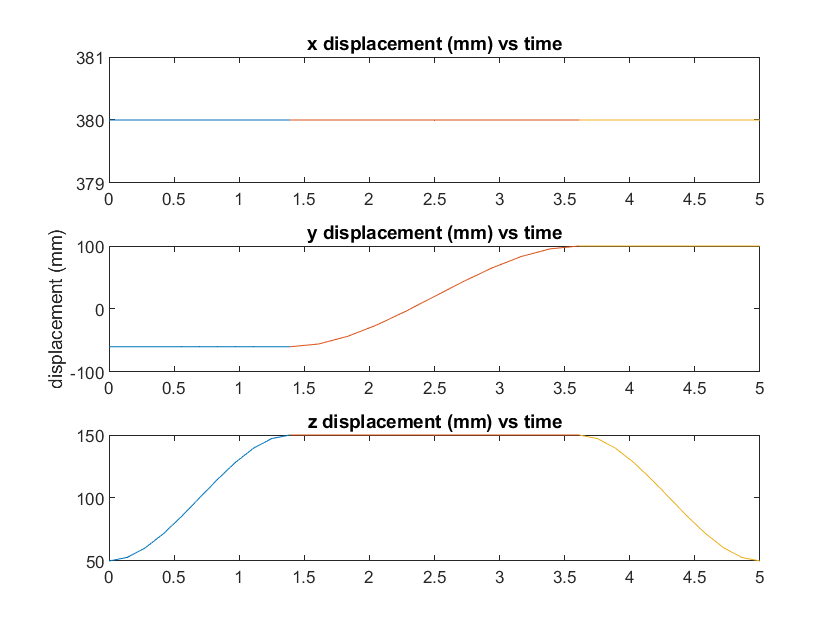


% plot 1
figure(1);
title('Location of the end-effector vs time');
for i = 1:3
    subplot(3,1,i);
    for j = 1:3
        if (i ==1)
            plot(t_array(:,j),x_array(:,j));hold on
            title('x displacement (mm) vs time');
        elseif(i ==2 )
            plot(t_array(:,j),y_array(:,j));hold on
            title('y displacement (mm) vs time');
            ylabel('displacement (mm)');
        else
            plot(t_array(:,j),z_array(:,j));hold on
            title('z displacement (mm) vs time');
        end
    end
end

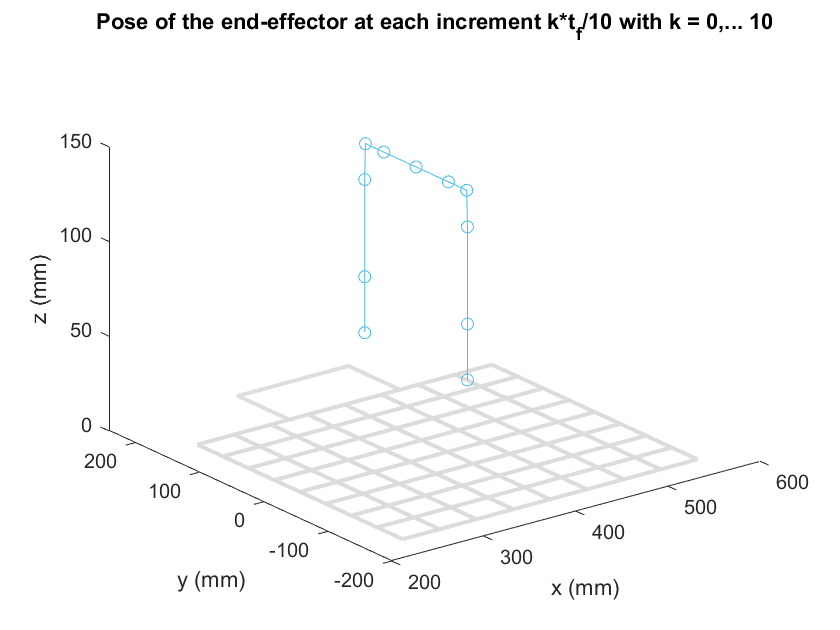

% plot 2,3

pose = zeros(4,1);
index = 1;
for k = 1:1:11
    t= (k-1)*t_f/10;
    time_array = [1;t;t^2;t^3];
%     delta = t_f/no_segments;
%     index = max(0,ceil(t/delta)-1);
    for j=index:length(time)-1
        if (t<=time(j+1))
            index = j - 1;
            pose(:,k) = [Arrays_coeff(1+3*index:min(3+3*index,length(Arrays_coeff(:,1))),:)*time_array;t];
            index = j;
            break;
        end
    end
end
figure(4);
plotChessBoard();hold on;
plot3(pose(1,:),pose(2,:),pose(3,:),'-o');
title('Pose of the end-effector at each increment k*t_f/10 with k = 0,... 10')
xlabel('x (mm)');
ylabel('y (mm)');
zlabel('z (mm)');

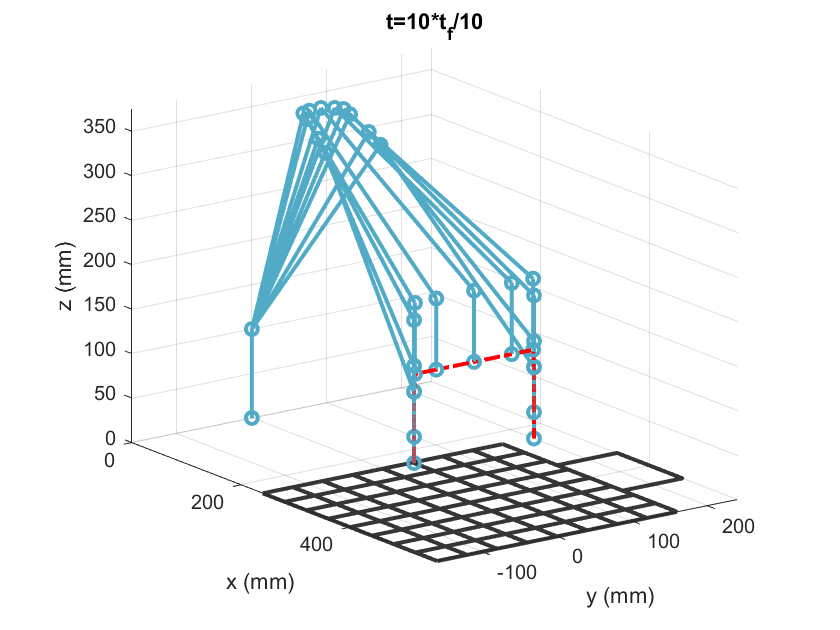

% Use Inverse Kinematics to find the joint displacement
% Use joints displacement to plot the stick plot of a robot arm
% plot 4

figure(5);
i = 1;
for i = 1:length(pose(1,:))
%     subplot(4,3,i);
    Q = InverseKinematicsGeneric(pose(:,i));
    Visualization(Q(1),Q(2),Q(3),Q(4));hold on;
    plot3(pose(1,:),pose(2,:),pose(3,:),'-.','Color','r',"LineWidth",2);
    title("Stick plot of the robot arm during the trajectory");
     view([110 -80 40]);
    hold on;
%     plotChessPiece(380,-20,0,50,20);
end

% Interpolating Orientation

function plotChessBoard()
    [X_chess, Y_chess, width_chess, singleSquare]= ChessboardSpec();
    
    colorChess = [ 	224, 224, 224]/260;
    for t = 1:9
    plot3([X_chess+width_chess*(t-1)/8 X_chess+width_chess*(t-1)/8],[-width_chess/2 -width_chess/2+width_chess],[Y_chess Y_chess],'color',colorChess,'LineWidth',2);
    hold on;
    plot3([X_chess X_chess+width_chess],[-width_chess/2+width_chess*(t-1)/8 -width_chess/2+width_chess*(t-1)/8],[Y_chess Y_chess],'color',colorChess,'LineWidth',2);
    hold on;
    end
    plot3([340;340;460;460],[160;240;240;160],[0;0;0;0],'LineWidth',2,'Color',colorChess+[0.01 0.01 0.01]);hold on
end

function [timearray] = getTimeArray(points,t_i, t_f)
distance = [];
timearray = [0];
totalT = t_f-t_i;
    for i = 1:length(points(1,:))-1
        distance(end+1) = norm(points(:,i+1)-points(:,i));
    end
    for i = 1:length(distance)
        timearray(i+1) = distance(i)/sum(distance) *totalT + timearray(i);
    end
end

function [phi_coeff,phi_omega_time, k_hat,R_t_array] = InterpolatingOrientation(XI,XF,t_i,t_f)
    % 1. identify R_F_i
    R_i_0 = RotationMatrix_EEdown_Eto0(XI);
    R_f_0 = RotationMatrix_EEdown_Eto0(XF);
    R_f_i = R_i_0'*R_f_0;
    R_t_array = []; % R from t to 0
    
    % 2. calculate the phi_f
    phi_f = 2 * acos( 1/2 * sqrt(1 + R_f_i(1,1) + R_f_i(2,2) + R_f_i(3,3)));
    
    % 3. identify k_hat
    k_hat = 1/(2*sin(phi_f))*[R_f_i(3,2) - R_f_i(2,3);...
                            R_f_i(1,3) - R_f_i(3,1);...
                            R_f_i(2,1) - R_f_i(1,2)];
    
    % 4. interpolate phi(t) using cubic polynomial
    [phi_coeff, phi_omega_time] = solveForSpline(0,phi_f,0,0,t_i,t_f);
    
    % 5. convert into Euler parameters and get the orientation R
    for i = 1:length(phi_omega_time(:,1))
        e1 = k_hat(1)*sin(phi_omega_time(i,1)/2);
        e2 = k_hat(2)*sin(phi_omega_time(i,1)/2);
        e3 = k_hat(3)*sin(phi_omega_time(i,1)/2);
        e4 = cos(phi_omega_time(i,1)/2);
        
        R = [1-2*e2^2-2*e3^2 2*(e1*e2-e3*e4) 2*(e1*e3+e2*e4);...
            2*(e1*e2+e3*e4) 1-2*e1^2-2*e3^2 2*(e2*e3-e1*e4);...
            2*(e1*e3 -e2*e4) 2*(e2*e3 + e1*e4) 1-2*e1^2-2*e2^2];
        
        R_t_array(i,:,:) =R_i_0* R;
    end
    
end
